# Leobardo de Jesús Carbajal

**Variables**

R = 1e3; 
L = 30; 
V = 6; 

## **Ejercicio 1**

inciso b)

t = 0.1;
I_inf = V / R;
tau = L / R;
I_t = I_inf * (1 - exp(-t/tau));
fprintf('La corriente después de 0.1 segundos es: %f A\n', I_t);

La corriente después de 0.1 segundos es: 0.005786 A


inciso c)

I_inf = V / R;
fprintf('El valor límite de la corriente es: %f A\n', I_inf);

El valor límite de la corriente es: 0.006000 A


inciso e)

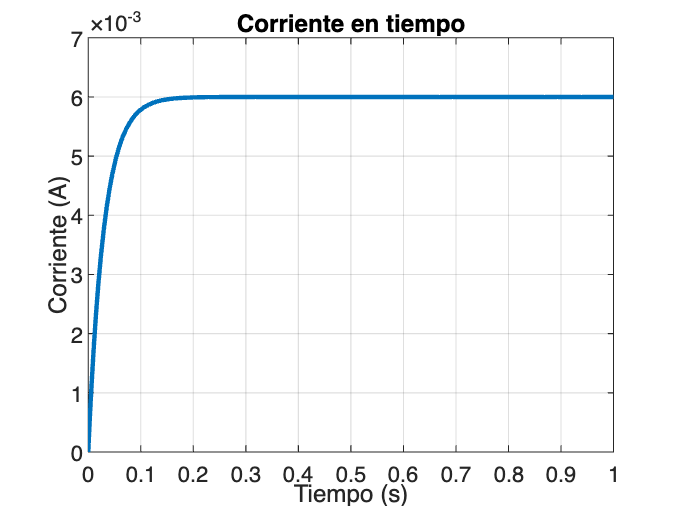



func = @(t, I) (V - R*I) / L;

I0 = 0;

tspan = [0 1];

[t, I] = ode45(func, tspan, I0);

I_inf = V / R;

figure;
plot(t, I, 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Corriente (A)');
title('Corriente en tiempo');
grid on;

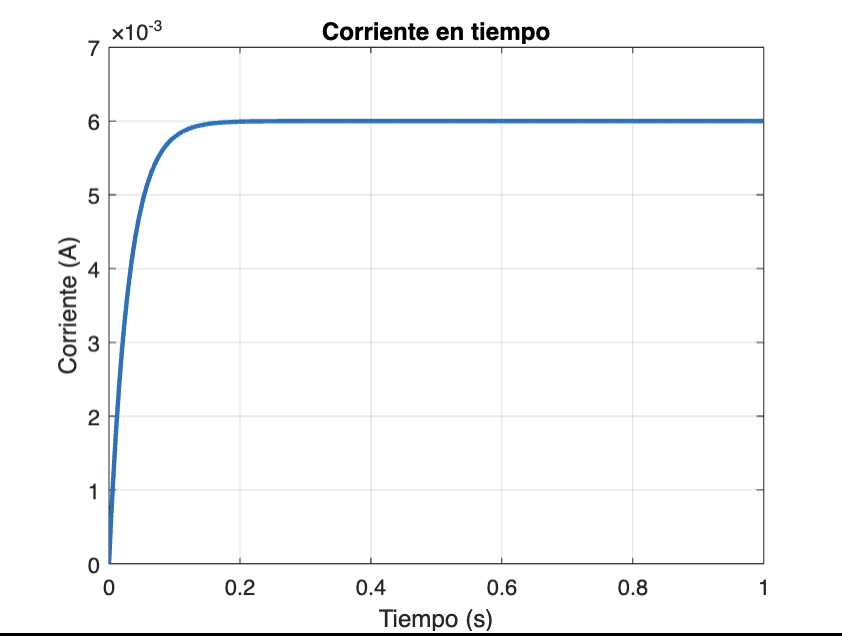

Inciso D)

tolerancia = 0.01;
tiempo_limite = interp1(I, t, (1-tolerancia)*I_inf);

fprintf('El tiempo para alcanzar el 99%% del valor límite de la corriente es aproximadamente %f segundos\n', tiempo_limite);

El tiempo para alcanzar el 99% del valor límite de la corriente es aproximadamente 0.138607 segundos


## Ejercicio 2

 b) Graficación

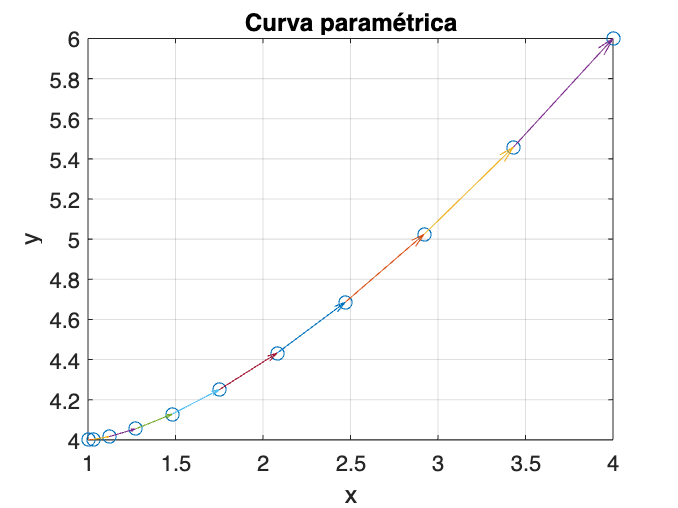

t = 0:0.1:1;

x = 1 + 3 * t.^2;
y = 4 + 2 * t.^3;

figure;
plot(x, y, '-o');
title('Curva paramétrica');
xlabel('x');
ylabel('y');
grid on;

hold on;
for i = 1:length(t)-1
    dp = [x(i+1) - x(i), y(i+1) - y(i)];
    quiver(x(i), y(i), dp(1), dp(2), 0, 'MaxHeadSize', 0.5);
end
hold off;

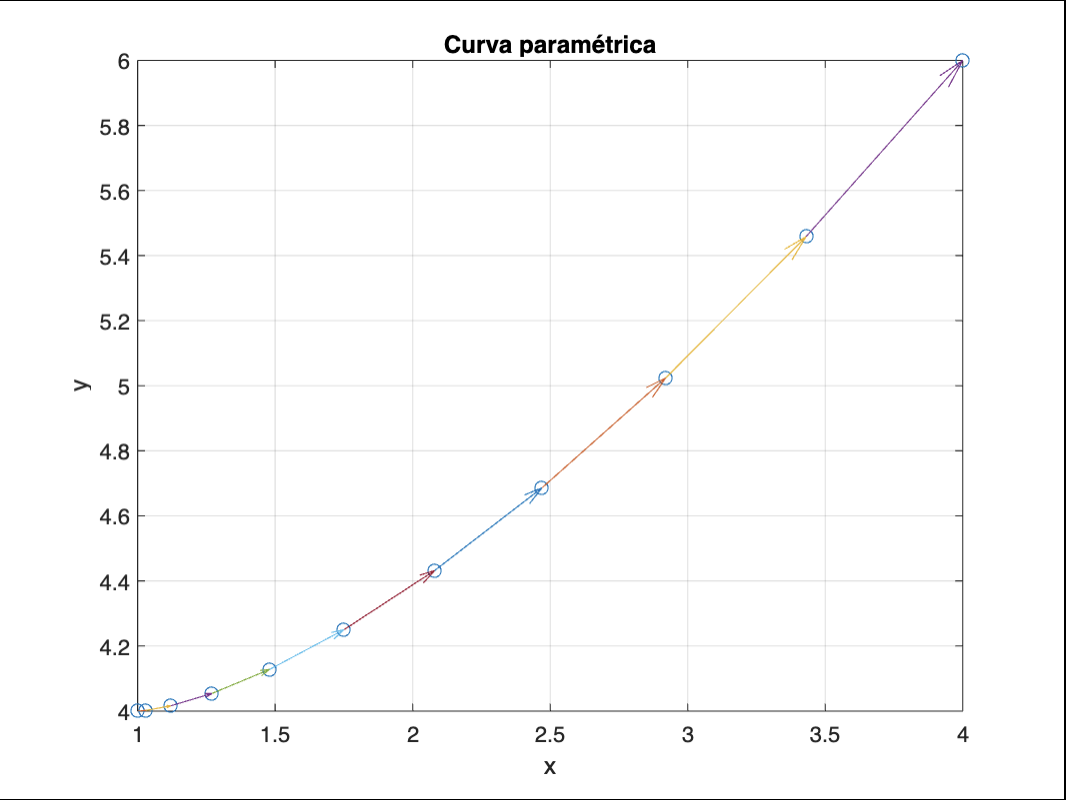

b) Longitud de arco

integrand = @(t) sqrt((6*t).^2 + (6*t.^2).^2);

L = integral(integrand, 0, 1);

fprintf('La longitud de arco es: %f u\n', L);

La longitud de arco es: 3.656854 u


## Bonus 

f = @(t) 2 + (cos(t).^2).*sin(t);

area = integral(f, 0, pi);

disp(['El área bajo la curva es: ', num2str(area)])

El área bajo la curva es: 6.9499


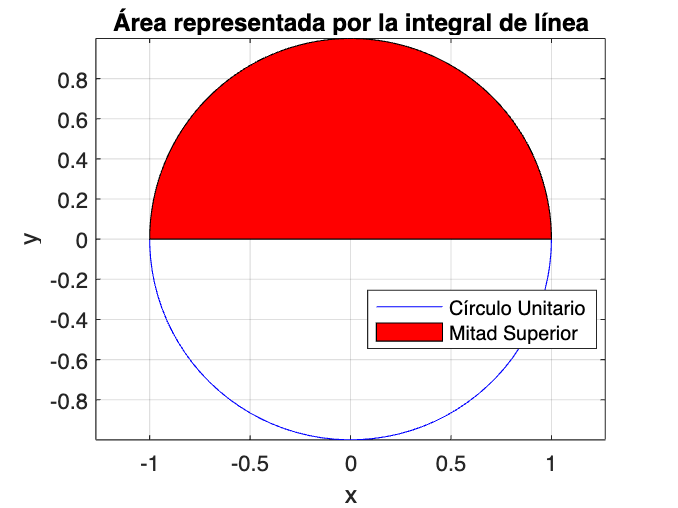


t = linspace(0, pi, 100);
x = cos(t);
y = sin(t);

theta = linspace(0, 2*pi, 100);
xcirc = cos(theta);
ycirc = sin(theta);

figure;
plot(xcirc, ycirc, 'b'); 
hold on;
fill(x, y, 'r'); 
title('Área representada por la integral de línea');
xlabel('x');
ylabel('y');
axis equal;
legend('Círculo Unitario', 'Mitad Superior', 'Location', 'best');
grid on
hold off;